clear
%tFinalL1 = 3.81101
%[0.7859 0 0 0.4276]
mMoon =7.348e22;% kg
mEarth = 5.9742e24; %kg
mu = mMoon/(mMoon + mEarth)

mu = 0.0122

C1 = jacobiConstant([0.7859 0],[0 0.4276],mu)

C1 = 3.1222


C2 = jacobiConst2([0.7859 0 0]',[0 0.4276 0]',mu)

C2 = 3.1222


C=C1

C = 3.1222

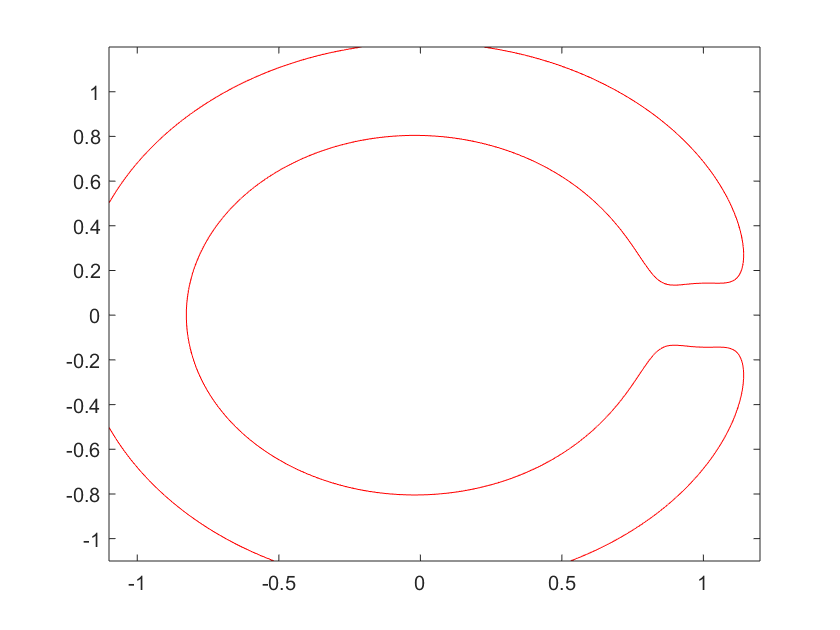


[X,Y]=meshgrid(-1.1:0.002:1.2);
r1 = ((X + mu).^2+Y.^2).^(1/2);
r2 = ((X + mu-1).^2+Y.^2).^(1/2);
Z = (X.^2 + Y.^2) + 2*(1-mu)./r1 + 2*mu./r2;
contour(X,Y,Z,[C, C],'r')